clear all;
%carico il dataset
load("data.mat")
input=[time,pw]

input =          0  144.4852
    0.0500  144.4852
    0.1000  144.4852
    0.1500  144.4852
    0.2000  144.4852
    0.2500  144.4852
    0.3000  170.8863
    0.3500  170.8863
    0.4000  170.8863
    0.4500  170.8863


%eseguo il simulink che ci è stato dato
sim("model2.mdl")

i = 1

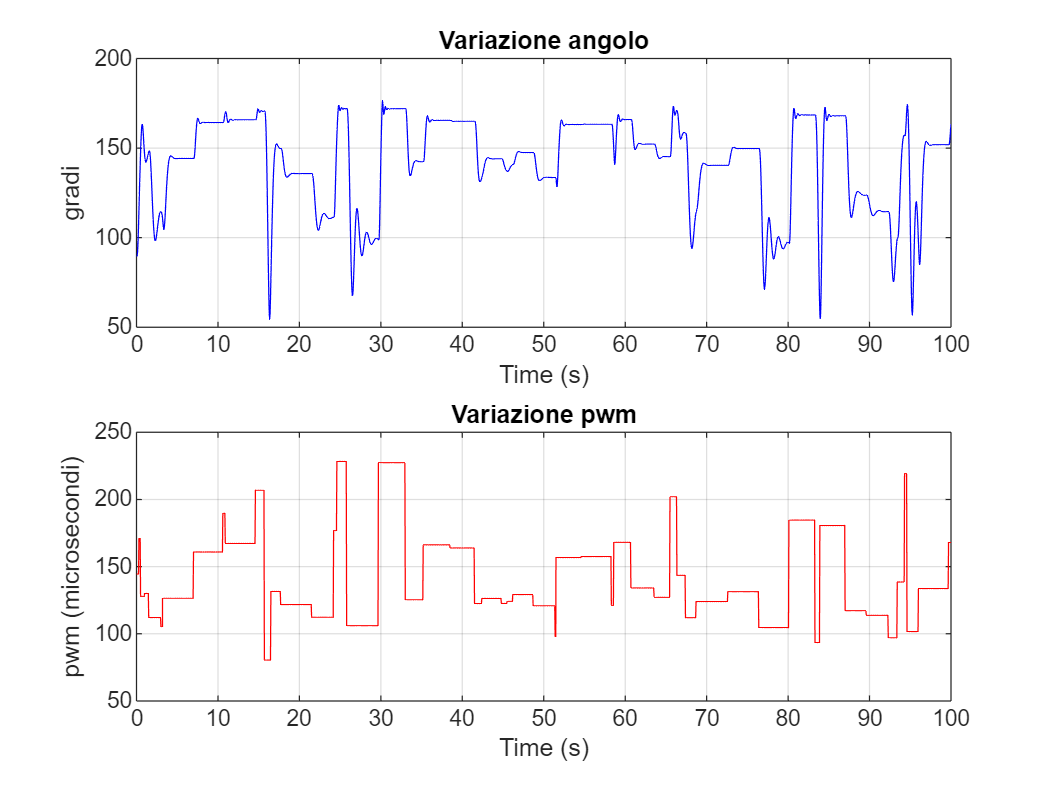

%stampo a video la variazione dell'angolo del ginocchio e quella del pwm
t = simulazione.time;

signal1 = simulazione.signals(1).values; % Primo segnale
signal2 = simulazione.signals(2).values; % Secondo segnale
plot_signals(t, signal1, signal2, 'Variazione angolo', 'Variazione pwm');

% andiamo alla ricerca di un punto d'equilibrio in cui linearizzare il
% sistema: scegliamo la media del pwm.
pe=116; %Uso il valore medio come punto di equilibrio (121 gradi)
pe=pe*ones(2001, 1);   %Matrice di solo valore media da mettere nel simulatore
input=[time,pe];
out_range=sim("model2.mdl")

i = 1

out_range =          0
    0.0000
    0.0000
    0.0002
    0.0009
    0.0044
    0.0139
    0.0254
    0.0382
    0.0500


%cerchiamo un intorno del punto d'equilibrio.
upper_bound = 120; %pw ci da 131 gradi circa
lower_bound = 112; %pw ci da 110 gradi circa

caso1: rumore bianco

%adesso andiamo ad eccitare il sistema con più segnali di input.

%caso 1: RUMORE BIANCO
rb = lower_bound + (upper_bound - lower_bound) * rand(2001, 1);
input=[time,rb];
sim("model2.mdl");

i = 1

%stampo a video la variazione dell'angolo del ginocchio e quella del pwm
% avente per ingresso un rumore bianco (rb)
t = simulazione.time;

signal_rb1 = simulazione.signals(1).values; % Primo segnale
signal_rb2 = simulazione.signals(2).values; % Secondo segnale
plot_signals(t, signal_rb1, signal_rb2, 'Variazione angolo (rb)', 'Variazione pwm (rb)');
%Procedo all'identificazione del processo con il Sytem Identification toolbox
% stima:70% , validazione: 30%
ts=0.05;
[dati_rb_ide, dati_rb_val]=prepare_iddata(y, u, ts, 0.7)


dati_rb_ide =

Time domain data set with 1401 samples.
Sample time: 0.05 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties

dati_rb_val =

Time domain data set with 600 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specified)   

model_rb=armax(dati_rb_ide,[4 4 1 1]);
display(model_rb);


model_rb =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)           
  A(z) = 1 - 2.966 z^-1 + 3.477 z^-2 - 1.951 z^-3 + 0.4585 z^-4     
                                                                    
  B(z) = -0.001738 z^-1 + 0.01796 z^-2 + 0.01931 z^-3 - 0.01649 z^-4
                                                                    
  C(z) = 1 + 0.8333 z^-1                                            
                                                                    
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=1   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using ARMAX on time domain data "dati_rb_ide".
Fit to estimation data: 99.47% (prediction focus)       
FPE: 0.0002468, MSE: 0.0002423                          
 


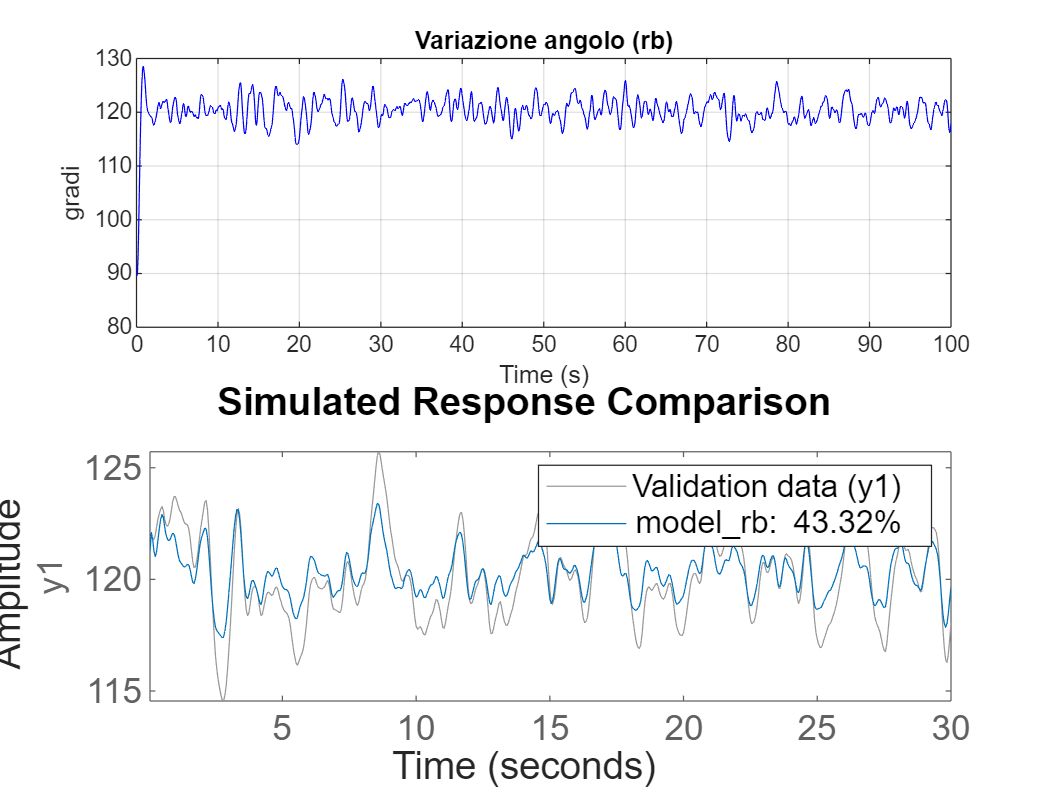

compare(dati_rb_val,model_rb)

caso2: sinusoide

% Adesso andiamo a eccitare il sistema con una sinusoide con ampiezza
% compresa fra l'intorno in cui vogliamo linearizzare il sistema.
amplitude = (upper_bound - lower_bound) / 2; % Ampiezza
offset = (upper_bound + lower_bound) / 2;   % Offset
% Parametri della sinusoide
frequency = 1;   % Frequenza in Hz
duration = 100;    % Durata totale in secondi
sampling_interval = 0.05; % Passo temporale in secondi
% Asse del tempo
durata = 0:sampling_interval:duration; % Campionamento a intervalli di 0.05 secondi
% Creazione della sinusoide
sinusoide = amplitude * sin(2 * pi * frequency * durata) + offset;
s=sinusoide';

input=[time,s];
sim("model2.mdl");

i = 1


%stampo a video la variazione dell'angolo del ginocchio e quella del pwm
% avente per ingresso una sinusoide (s)
t = simulazione.time;

signal_s1 = simulazione.signals(1).values; % Primo segnale
signal_s2 = simulazione.signals(2).values; % Secondo segnale
plot_signals(t, signal_s1, signal_s2, 'Variazione angolo (sin)', 'Variazione pwm (sin)');
%Procedo all'identificazione del processo con il Sytem Identification toolbox
% stima:70% , validazione: 30%
ts=0.05;

[dati_s_ide,dati_s_val]=prepare_iddata(y, u, ts, 0.7)


dati_s_ide =

Time domain data set with 1401 samples.
Sample time: 0.05 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties

dati_s_val =

Time domain data set with 600 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specified)       
  

model_s=armax(dati_s_ide,[4 4 1 1]);
display(model_s);


model_s =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)     
  A(z) = 1 - 3.316 z^-1 + 4.445 z^-2 - 2.85 z^-3 + 0.7313 z^-4
                                                              
  B(z) = -0.1273 z^-1 + 0.1078 z^-2 + 0.146 z^-3 - 0.1147 z^-4
                                                              
  C(z) = 1 + 0.975 z^-1                                       
                                                              
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=1   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using ARMAX on time domain data "dati_s_ide".
Fit to estimation data: 99.93% (prediction focus)      
FPE: 1.274e-05, MSE: 1.251e-05                         
 


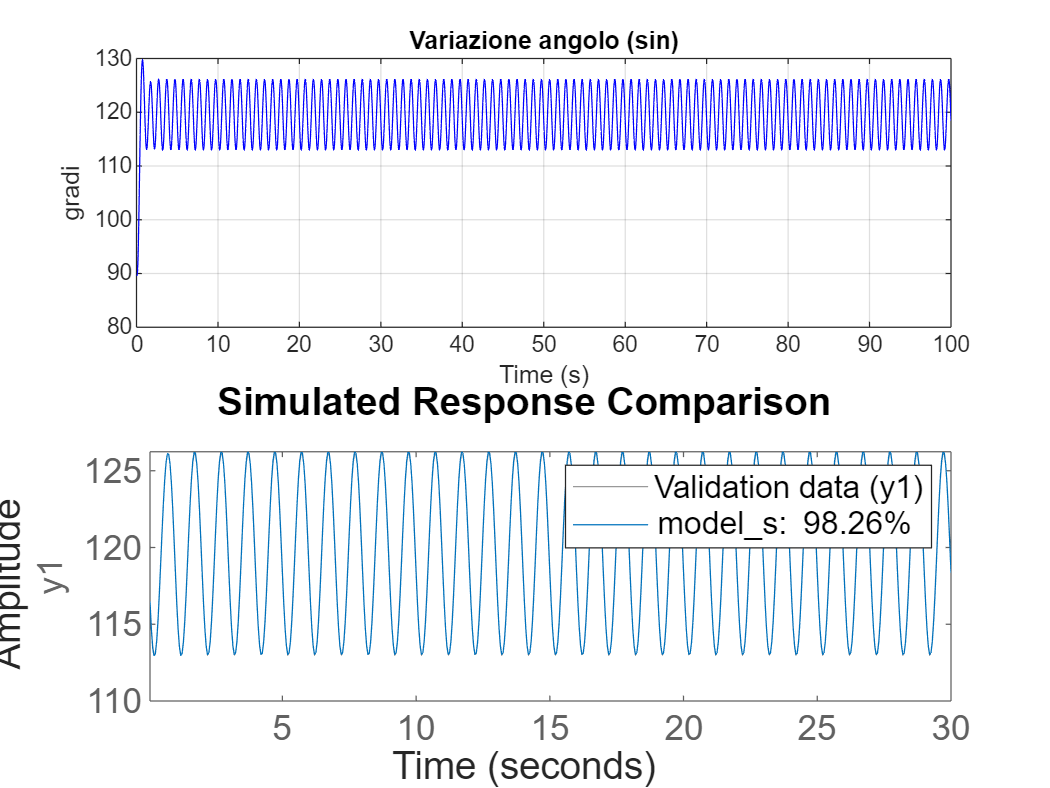

compare(dati_s_val,model_s);

% la sinusoide segue bene, ma perchè i dati di validazione sono alla
% medesima frequenza...proviamo a fargi seguire una sinusoide ad una f
% diversa.

nuova_s=amplitude * sin(2 * pi * (frequency +4 )* durata) + offset;
nuova_s=nuova_s';

%adesso eseguo il simulink avendo come input
input=[time,nuova_s];
sim("model2.mdl");

i = 1

[dati_prova_ide,dati_prova_val]=prepare_iddata(y, u, ts, 0.7)


dati_prova_ide =

Time domain data set with 1401 samples.
Sample time: 0.05 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties

dati_prova_val =

Time domain data set with 600 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       U

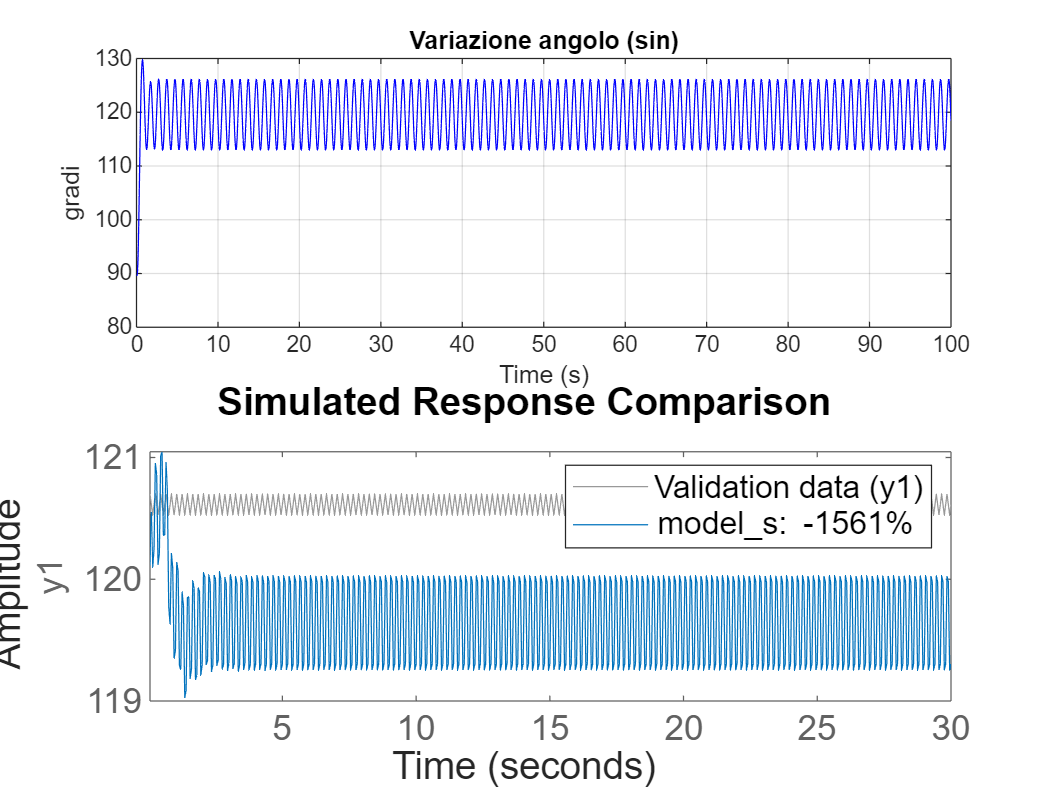

compare(dati_prova_val , model_s)

% dal grafico vediamo che la sinusoide si dimostra essere un pessimo
% ingresso per eccitare il sistema

caso3: PRBS (Pseudo-Random Binary Signal)

%andiamo adesso ad eccitare il sistema con il segnale PRBS.
amplitude = [lower_bound, upper_bound];
%creo il segnale
prbs = idinput(2001, 'prbs', [0 0.7], amplitude);


%load("prbs.mat")
input=[time,prbs];
sim("model2.mdl");

i = 1

%stampo a video la variazione dell'angolo del ginocchio e quella del pwm
% avente per ingresso una sinusoide (s)
t = simulazione.time;

signal_prbs1 = simulazione.signals(1).values; % Primo segnale
signal_prbs2 = simulazione.signals(2).values; % Secondo segnale
plot_signals(t, signal_prbs1, signal_prbs2, 'Variazione angolo (prbs)', 'Variazione pwm (prbs)')
%Procedo all'identificazione del processo con il Sytem Identification toolbox
% stima:70% , validazione: 30%
ts=0.05;


[dati_prbs_ide,dati_prbs_val]=prepare_iddata(y, u, ts, 0.7)


dati_prbs_ide =

Time domain data set with 1401 samples.
Sample time: 0.05 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties

dati_prbs_val =

Time domain data set with 600 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if

model_prbs=armax(dati_prbs_ide,[4 4 1 1]);
display(model_prbs);


model_prbs =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)           
  A(z) = 1 - 3.129 z^-1 + 3.839 z^-2 - 2.222 z^-3 + 0.5249 z^-4     
                                                                    
  B(z) = -0.001132 z^-1 + 0.01938 z^-2 + 0.01725 z^-3 - 0.02282 z^-4
                                                                    
  C(z) = 1 + 0.6011 z^-1                                            
                                                                    
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=1   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                   
Estimated using ARMAX on time domain data "dati_prbs_ide".
Fit to estimation data: 99.4% (prediction focus)          
FPE: 0.0006966, MSE: 0.0006838                            
 


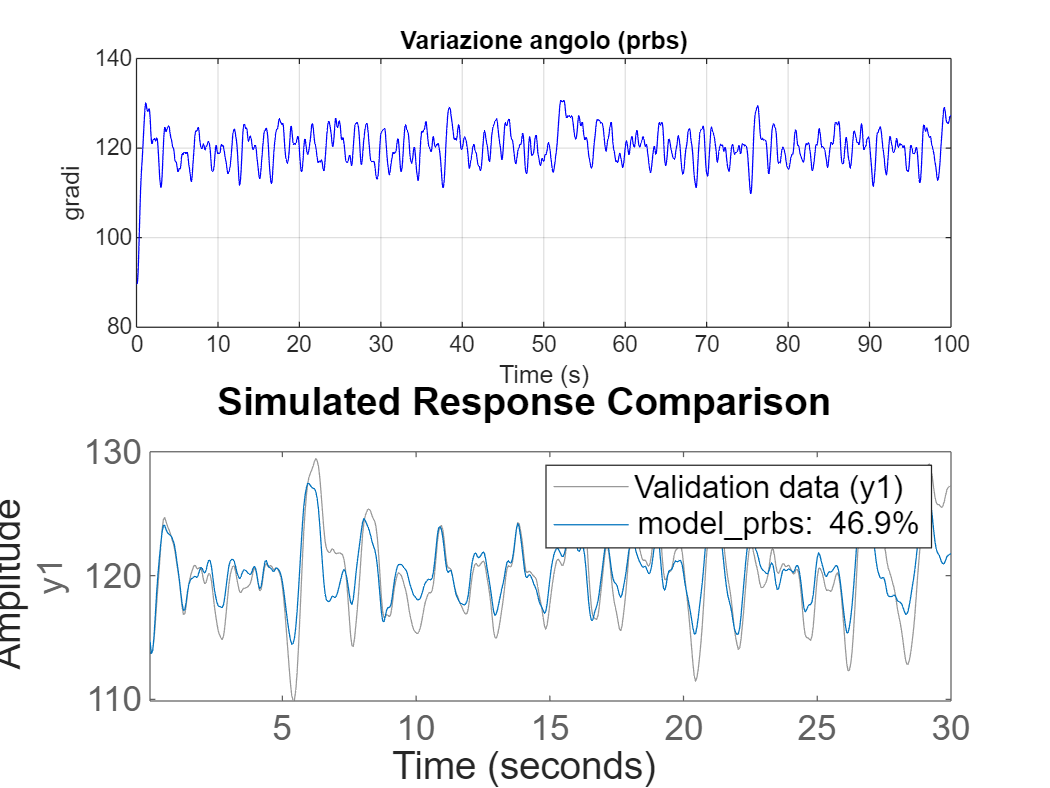

compare(dati_prbs_val,model_prbs);

caso 4: rumore bianco a blocchi di 60 valori costanti (rbb)


 % total_length = 2001;  % Lunghezza totale del segnale
 % block_size = 60;      % Dimensione di ciascun blocco
 % n_blocks = ceil(total_length / block_size);
 % block_values = lower_bound + (upper_bound - lower_bound) * rand(n_blocks, 1);
 % rbb = repelem(block_values, block_size);
 % rbb = rbb(1:total_length);
load("rbb.mat")
input=[time,rbb];
sim("model2.mdl");

i = 1

%stampo a video la variazione dell'angolo del ginocchio e quella del pwm
% avente per ingresso un rumore bianco a blocchi (rbb)
t = simulazione.time;

signal_rbb1 = simulazione.signals(1).values; % Primo segnale
signal_rbb2 = simulazione.signals(2).values; % Secondo segnale
plot_signals(t, signal_rbb1, signal_rbb2, 'Variazione angolo (rbb)', 'Variazione pwm (rbb)');
%Procedo all'identificazione del processo con il Sytem Identification toolbox
% stima:70% , validazione: 30%
ts=0.05;
[dati_rbb_ide, dati_rbb_val]=prepare_iddata(y, u, ts, 0.7)


dati_rbb_ide =

Time domain data set with 1401 samples.
Sample time: 0.05 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties

dati_rbb_val =

Time domain data set with 600 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specif

model_rbb=armax(dati_rbb_ide,[5 4 1 2]);
display(model_rbb);


model_rbb =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)                     
  A(z) = 1 - 3.381 z^-1 + 4.395 z^-2 - 2.702 z^-3 + 0.7673 z^-4 - 0.07916 z^-5
                                                                              
  B(z) = 0.02173 z^-2 + 0.01412 z^-3 - 0.0312 z^-4 - 0.004628 z^-5            
                                                                              
  C(z) = 1 + 0.7979 z^-1                                                      
                                                                              
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=4   nc=1   nk=2
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using ARMAX on time domain data "dati_rbb_ide".
Fit to estimation data: 99.98% (prediction focus)        
FPE: 1.161e-06, MSE: 1.136e-06                  

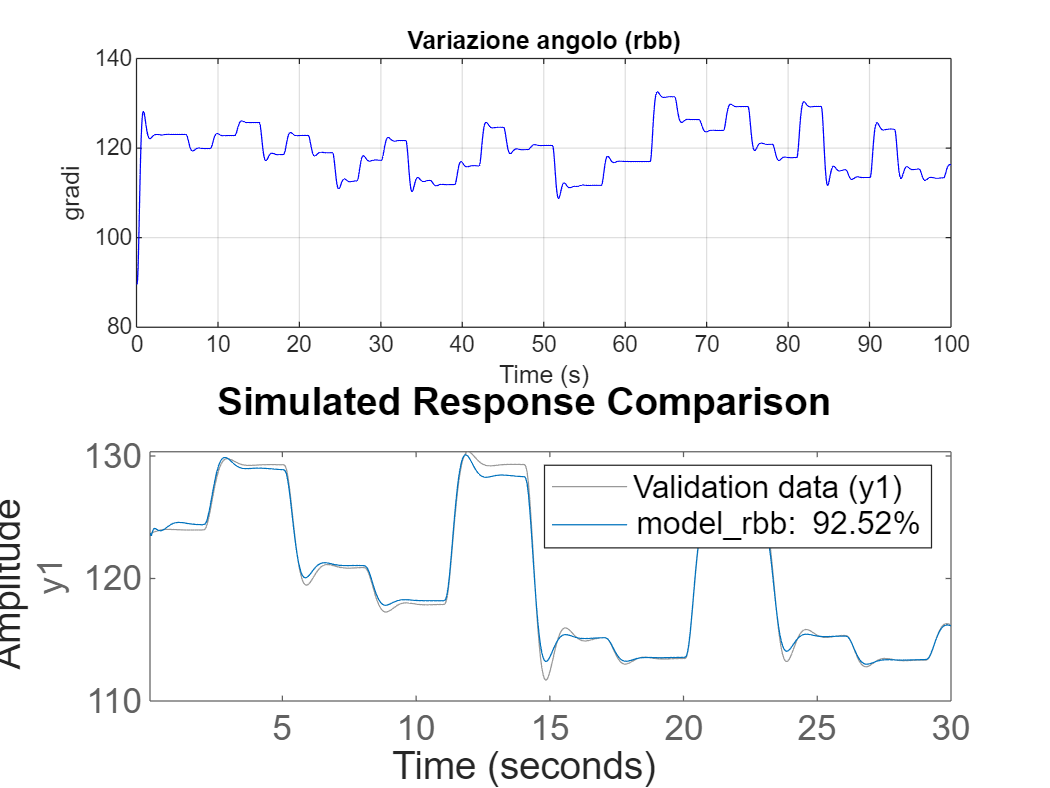

compare(dati_rbb_val,model_rbb)

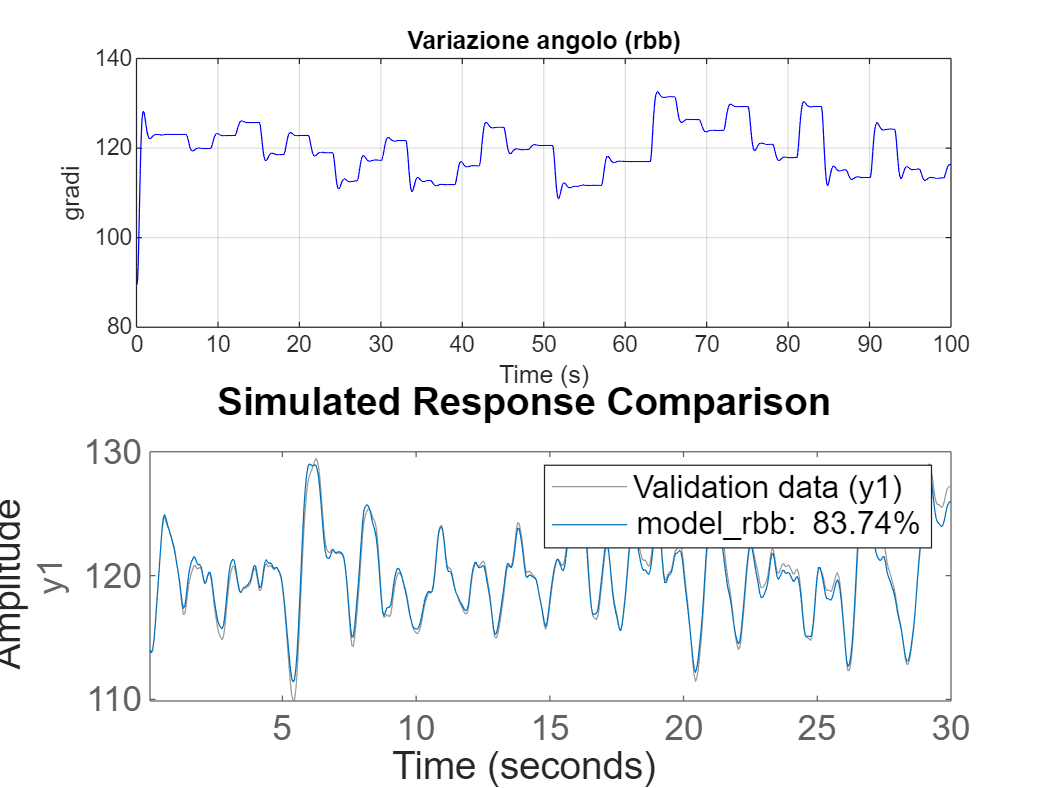

% adesso compariamo il miglio modello trovato con gli altri segnali per
% capire se il valore alto è dovuto a overfitting o meno.
compare(dati_prbs_val,model_rbb)

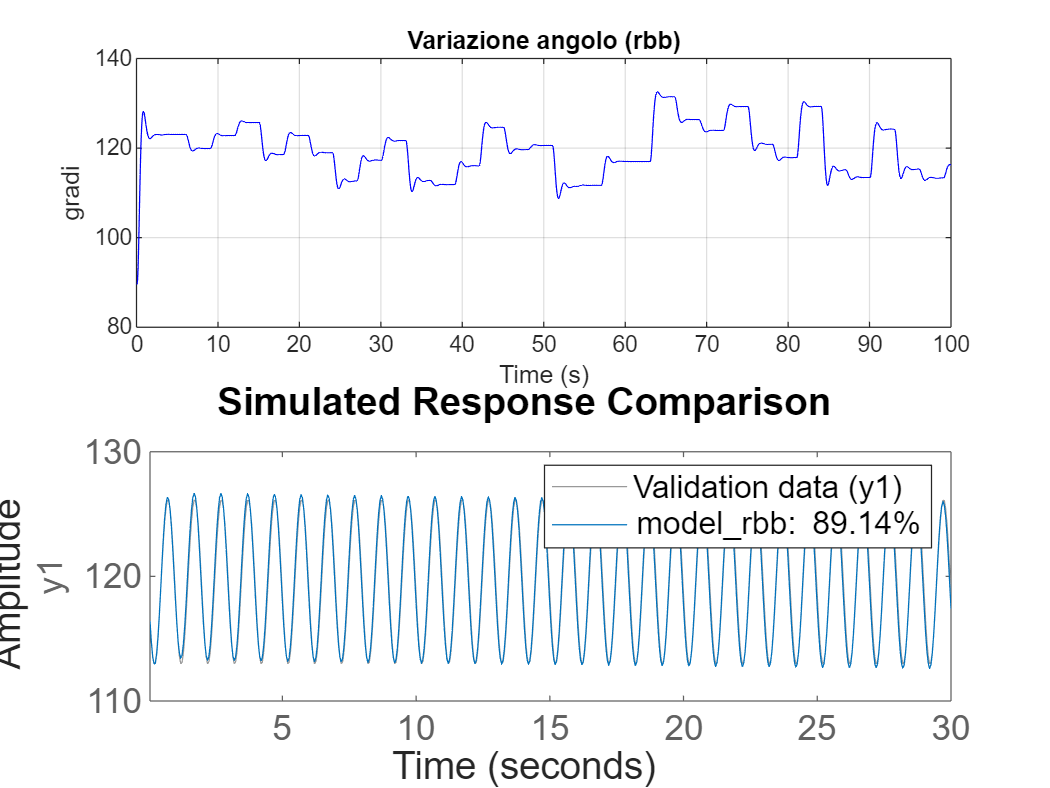

compare(dati_s_val,model_rbb)

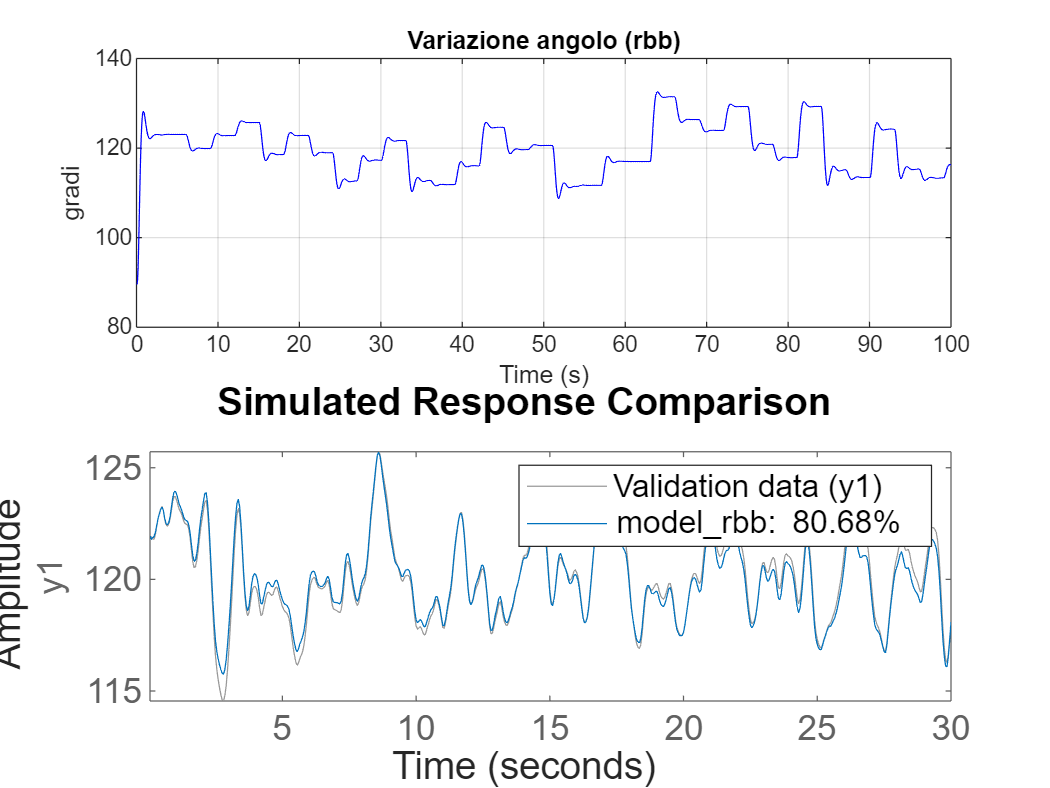


compare(dati_rb_val,model_rbb)

ultimo caso: multiseno.

%u_ms = creaMultiSin(112,120,0.05,0.5,1.5)
%u_ms=u_ms(1:2001)
load("u_ms.mat")
input=[time,u_ms];
sim("model2.mdl");

i = 1


t = simulazione.time;

signal_ms1 = simulazione.signals(1).values; % Primo segnale
signal_ms2 = simulazione.signals(2).values; % Secondo segnale
plot_signals(t, signal_ms1, signal_ms2, 'Variazione angolo (ms)', 'Variazione pwm (ms)')
ts=0.05;


[dati_ms_ide,dati_ms_val]=prepare_iddata(y, u, ts, 0.7)


dati_ms_ide =

Time domain data set with 1401 samples.
Sample time: 0.05 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties

dati_ms_val =

Time domain data set with 600 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specified)   

model_ms=armax(dati_ms_ide,[4 4 1 1]);
display(model_ms);


model_ms =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)       
  A(z) = 1 - 3.053 z^-1 + 3.369 z^-2 - 1.545 z^-3 + 0.2288 z^-4 
                                                                
  B(z) = -0.0987 z^-1 + 0.2802 z^-2 - 0.1935 z^-3 + 0.01189 z^-4
                                                                
  C(z) = 1 + 0.9268 z^-1                                        
                                                                
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=1   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using ARMAX on time domain data "dati_ms_ide".
Fit to estimation data: 99.81% (prediction focus)       
FPE: 3.523e-05, MSE: 3.458e-05                          
 


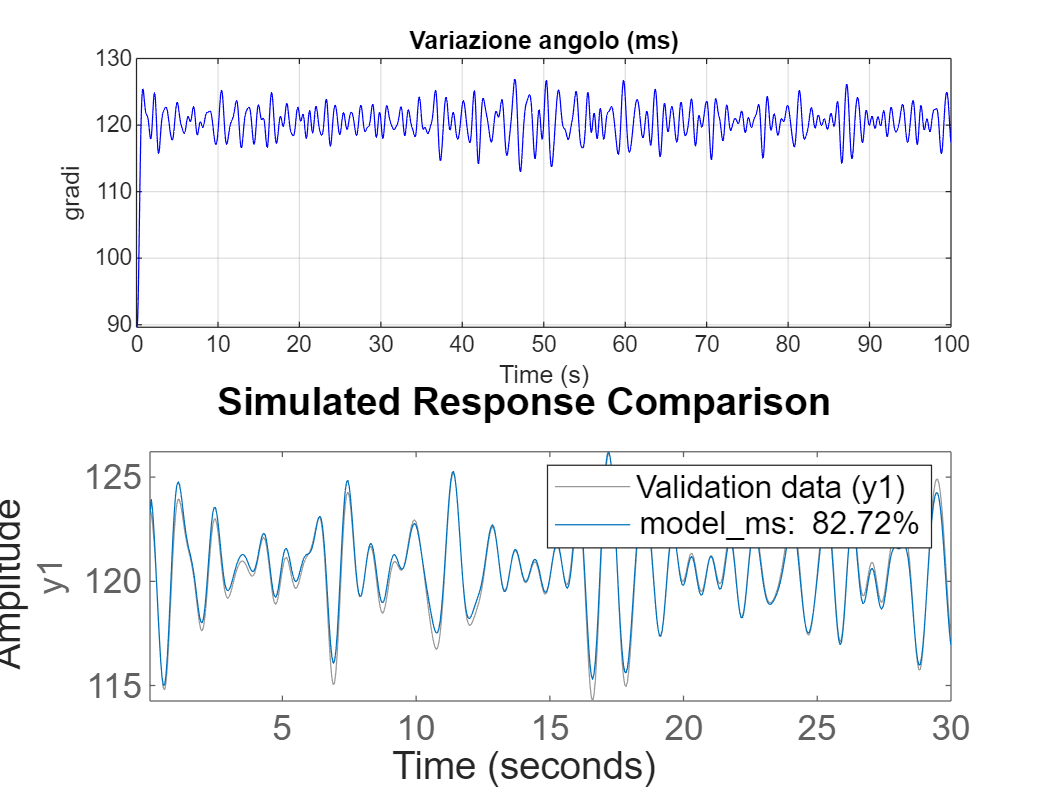

compare(dati_ms_val,model_ms);

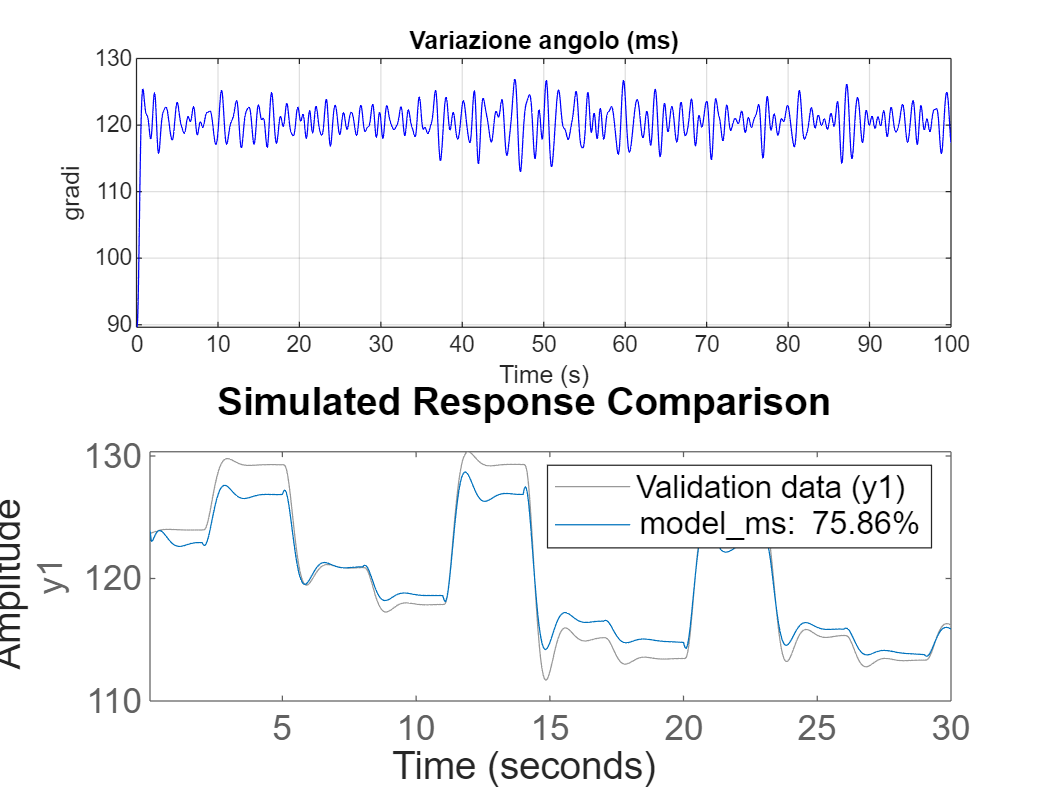

compare(dati_rbb_val,model_ms)

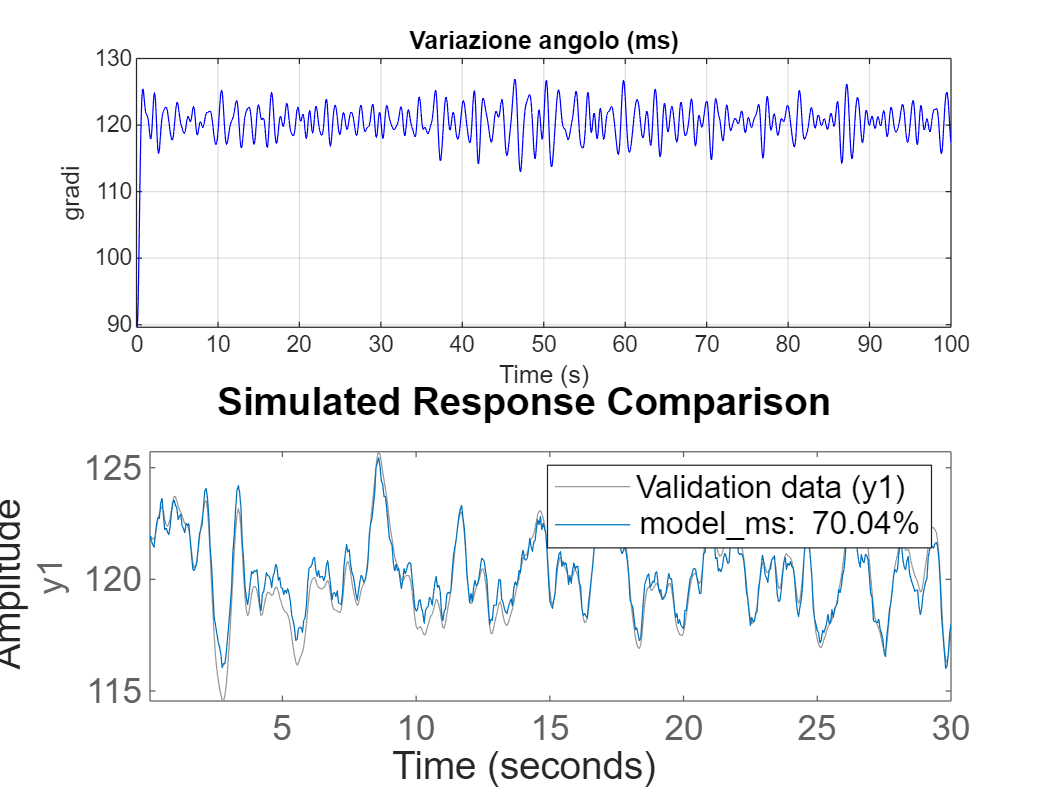

compare(dati_rb_val,model_ms)

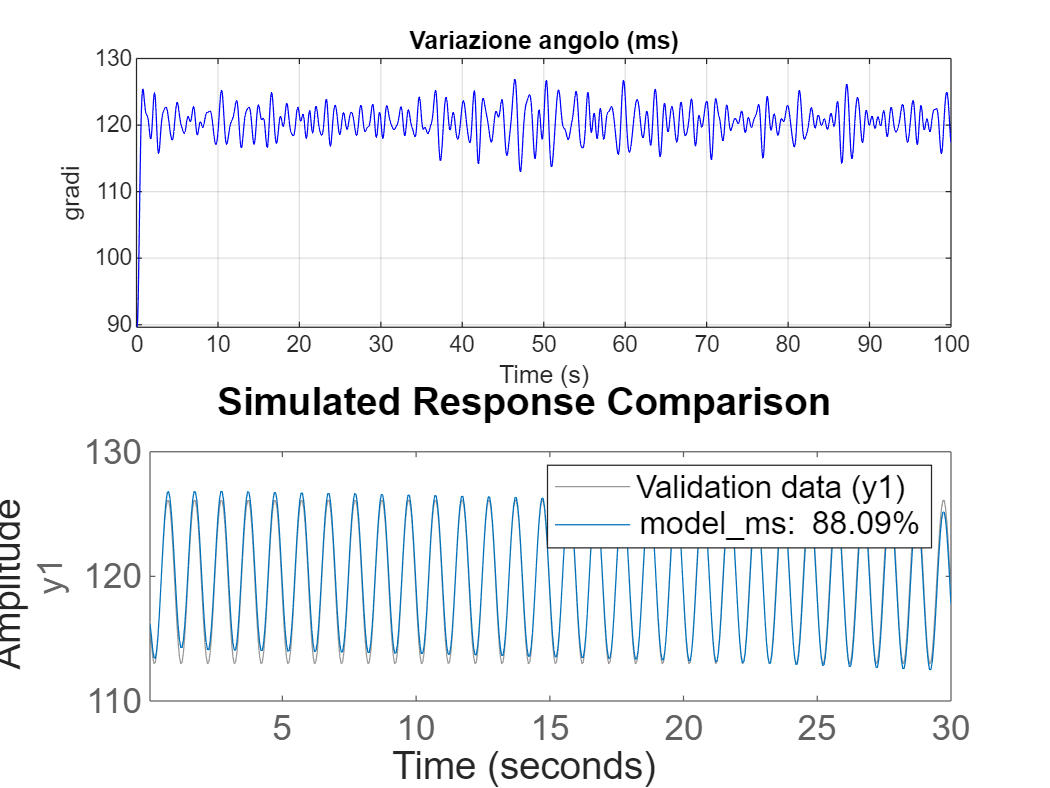

compare(dati_s_val,model_ms)

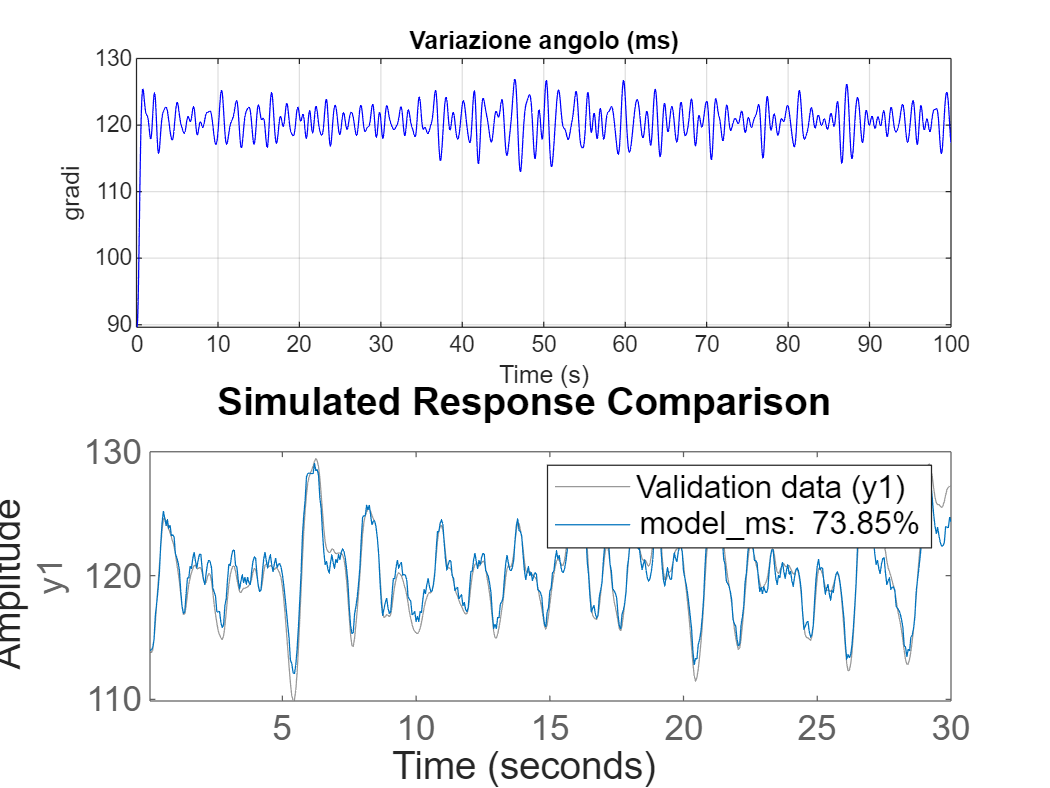

compare(dati_prbs_val,model_ms)